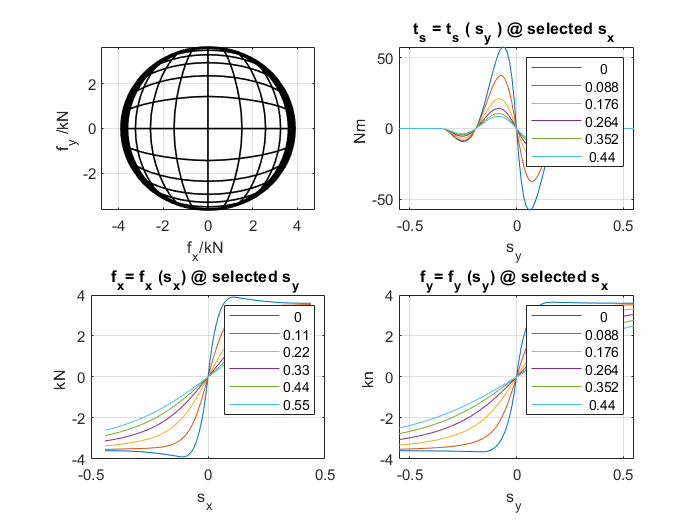

% tire properties : unloaded radius , payload , vertical stiffness
 r0 = 0.293; fz0 = 3500; cz =190000;

% tire characteristics in long . and lat . directions
 dfx0 = 100000; dfy0 = 80000; % init slopes in N/-
 fxm = 3900; fym = 3650; % maximum forces in N
 sxm = 0.110; sym = 0.160; % sm where f(sm) = fm
 fxs = 3600; fys = 3600; % sliding forces in N
 sxs = 0.400; sys = 0.500; % ss where f(ss) = fs

% dynamic tire offset parameter
n0 = 0.180; % normalized tire offset n/L @ sy = 0
sy0 = 0.190; % sy where n/L passes sy - axis
syE = 0.350; % sy where n/L approaches sy - axis again

% compute slip normalizing factors
 hsxn = sxm /( sxm +sym ) + ( fxm / dfx0 )/( fxm / dfx0 + fym / dfy0 );
 hsyn = sym /( sxm +sym ) + ( fym / dfy0 )/( fxm / dfx0 + fym / dfy0 );

 nvar = 101; % generate various slip values
 sx = linspace (-1,1, nvar )*1.1* max ( sxs );
 sy = linspace (-1,1, nvar )*1.1* max ( sys );
 % pre - allocate fx , fy and ts to speed up loop
 fx = zeros ( length (sx), length (sy )); fy=fx; ts=fx;

 % compute tire forces , tire offset , and self - align . torque
 L = 2* sqrt (r0* fz0 /cz ); % contact length
 for j = 1: nvar
 to = L* tmy_tireoff ( sy(j), n0 ,sy0 , syE );
 syn = sy(j)/ hsyn ;
 for i = 1: nvar
 % combined slip
 sxn = sx(i)/ hsxn ;
 sc = sqrt ( sxn ^2 + syn ^2 );
 if sc > 0
 cphi = sxn /sc; sphi =syn /sc;
 else
 cphi = sqrt (2)/2; sphi = sqrt (2)/2;
end
 % combined characteristic for normalized slip values
 df0 = sqrt ( ( dfx0 * hsxn * cphi )^2 + ( dfy0 * hsyn * sphi )^2 );
 fm = sqrt ( ( fxm * cphi )^2 + (fym * sphi )^2 );
 sm = sqrt ( ( sxm / hsxn * cphi )^2 + ( sym / hsyn * sphi )^2 );
 fs = sqrt ( ( fxs * cphi )^2 + (fys * sphi )^2 );
 ss = sqrt ( ( sxs / hsxn * cphi )^2 + ( sys / hsyn * sphi )^2 );
 % combined tire force
 [ f, ~ ] = tmy_fcombined ( sc , df0 ,fm ,sm ,fs ,ss );
 % split into longitudinal and lateral forces
 fx(i,j) = f* cphi ; fy(i,j) = f* sphi ;
 % compute self - aligning torque
 ts(i,j) = -to*fy(i,j);
 end
 end

 fx=fx /1000; fy=fy /1000; % N --> kN
 hsp1 = subplot (2 ,2 ,1); is =1:2: nvar ; % reduced samples
 plot (fx (:, is),fy (:, is),'k', 'LineWidth' ,1) , hold on
 plot (fx(is ,:).'  , fy(is ,:).' , 'k', 'LineWidth',1) , grid on
 xlabel ( 'f_x/kN '), ylabel ('f_y /kN '), axis equal
 hsp2 = subplot (2 ,2 ,2); is= round (( nvar +1)/2):10: nvar ; % selection
 plot (sy ,ts(is ,:).' ) , grid on , title ('t_s = t_s ( s_y ) @ selected s_x ')
 xlabel ('s_y '), ylabel ('Nm '), legend ( num2str (sx(is ).' ))
 hsp3 = subplot (2 ,2 ,3);
 plot (sx ,fx (:, is )), grid on , xlabel ('s_x '), ylabel ('kN ')
 title ('f_x= f_x (s_x) @ selected s_y '), legend ( num2str (sy(is ).' ))
 hsp4 = subplot (2 ,2 ,4);
 plot (sy ,fy(is ,:).' ) , grid on , xlabel ('s_y '), ylabel ('kn ')
 title ('f_y= f_y (s_y) @ selected s_x ' ), legend ( num2str (sx(is ).'))  